clc; clear;

Load in ground truth RGB value

load("mat data\Colorchecker00_original_linear_RGBValue_BLACK.mat")

Load Kd value

load("mat data\Kd_RGB_database.mat");
d = [1 5]; %depth
typename = {'JerlovI','JerlovIA','JerlovIB','JerlovII','JerlovIII','Jerlov1C','Jerlov3C','Jerlov5C'};
fpath = 'C:\Users\lingoiapple\OneDrive - 國立台灣大學\JJJ\11 碩一 上下 2021-2022\study_水下攝影測量\水下攝影測量\04 計畫\模擬資料\資料整理\Kd_image\'

fpath = 'C:\Users\lingoiapple\OneDrive - 國立台灣大學\JJJ\11 碩一 上下 2021-2022\study_水下攝影測量\水下攝影測量\04 計畫\模擬資料\資料整理\Kd_image\'

Calculate color checker RGB under depth d

sRGB_Kd =     0.8194
    0.1832
    0.7208
    0.3840
    0.6731
    0.2309
    0.2649
    0.6527
    0.5371
    0.5881


sRGB_Kd =     0.8194
    0.1832
    0.7208
    0.3840
    0.6731
    0.2309
    0.2649
    0.6527
    0.5371
    0.5881


sRGB_Kd =     0.8194
    0.1832
    0.7208
    0.3840
    0.6731
    0.2309
    0.2649
    0.6527
    0.5371
    0.5881


sRGB_Kd =     0.8194
    0.1832
    0.7208
    0.3840
    0.6731
    0.2309
    0.2649
    0.6527
    0.5371
    0.5881


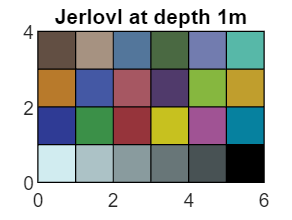

Error using saveas
Invalid or missing path: C:\Users\lingoiapple\OneDrive - 國立台灣大學\JJJ\11 碩一 上下 2021-2022\study_水下攝影測量\水下攝影測量\04 計畫\模擬資料\資料整理\Kd_image\Kd_JerlovI at depth 1m_BLACK

for i = 1:numel(typename) % jerlov 8 types
    for j = 1:numel(d) %水深 2 depth
        Kd = Kd_Jerlov_RGB(:,i);
        linearR_Kd(:,i,j) = (R_linear.* exp(-Kd(1)*d(j)))';
        linearG_Kd(:,i,j) = (G_linear.* exp(-Kd(2)*d(j)))';
        linearB_Kd(:,i,j) = (B_linear.* exp(-Kd(3)*d(j)))';
        linearRGB_Kd = [linearR_Kd(:,i,j);linearG_Kd(:,i,j);linearB_Kd(:,i,j)];

        % Turn into sRGB
        threshold = 0.0031308;
        for k = 1:72
            if linearRGB_Kd(k,1) > threshold
                sRGB_Kd(k,1) = 1.055*(linearRGB_Kd(k,1)^(1/2.4))-0.055;
            else
                sRGB_Kd(k,1) = 12.92*linearRGB_Kd(k,1)
            end
        end
        sR_Kd(:,i,j) = sRGB_Kd(1:24);
        sG_Kd(:,i,j) = sRGB_Kd(25:48);
        sB_Kd(:,i,j) = sRGB_Kd(49:72);

        % Plot colorchecker
        plotcolorpatch(sR_Kd(:,i,j),sG_Kd(:,i,j),sB_Kd(:,i,j))
        title(strcat(typename{i}," at depth ",num2str(d(j)),'m'))
%         set(gcf,"Visible","on")
        saveas(gcf,strcat(fpath,'Kd_',typename{i}," at depth ",num2str(d(j)),'m_BLACK'),'bmp')
    end
end

save linear Kd RGB value

fpath = 'C:\Users\lingoiapple\OneDrive - 國立台灣大學\JJJ\11 碩一 上下 2021-2022\study_水下攝影測量\水下攝影測量\04 計畫\模擬資料\mat data\';
% save(strcat(fpath, "Colorchecker01_Kd_linear_RGBValue.mat"),"linearR_Kd","linearG_Kd","linearB_Kd")
save(strcat(fpath, "Colorchecker01_Kd_linear_RGBValue_BLACK.mat"),"linearR_Kd","linearG_Kd","linearB_Kd")

function plotcolorpatch(R,G,B)
Nr_R = reshape(R, 4, 6);
Nr_G = reshape(G, 4, 6);
Nr_B = reshape(B, 4, 6);
%%
x = 0 : 6;
y = 0 : 4;
%% 網格xy首末
x1 = [x(1) x(end)]';
y1 = [y(1) y(end)]';

%% 繪製網格
figure

%% 填色至各網格
for i = 1:4
    for j = 1:6
        xx = [0 1 1 0] + j - 1;
        yy = [0 0 1 1] + i - 1;
        patch('xData', xx, 'yData', yy, 'FaceColor', [Nr_R(i,j) Nr_G(i,j) Nr_B(i,j)]);
    end
end
axis equal
xlim(x1)
ylim(y1)
end